# Produit Volatilité 1 - Note à volatilité avec participation adaptative

Le produit actions considéré dans cette section est une note à capital protégé versant des coupons mensuels dont le niveau dépend de la volatilité réalisée du sous-jacent, ici l’ETF canadien ZCN, ainsi que de la fréquence passée des épisodes de forte volatilité. L’objectif est de construire un produit cohérent avec le besoin client, soit des revenus relativement stables mais croissants lorsque la volatilité de marché augmente.

Sous la mesure risque neutre Q, le sous-jacent est modélisé par un modèle de Heston calibré précédemment sur les données d’options. Ce choix permet de générer des trajectoires de prix avec volatilité stochastique, donc de produire une distribution réaliste des volatilités réalisées futures. Même si le payoff dépend de la volatilité réalisée observée sur chaque sous-période, la variable latente $v_t$ du modèle joue un rôle central, puisqu’elle gouverne la dynamique de $S_t$ et, indirectement, celle de la volatilité réalisée utilisée dans le coupon.

On a déja calibré notre modèle de Heston, et les paramètres trouvés sont les suivant:

kappa  = 9.766785;   
theta  = 0.033274;   
xi     = 1.921424;   
rho    = -0.746108;   
v0     = 0.007872;       % variance initiale (GJR annualisé)
S0     = 44.29;          % spot ZCN au 2 avril 2026
r      = 0.0253;     
q      = 0.02143814;     

La maturité du produit est fixée à un an, avec douze dates d’observation et de paiement mensuelles. Pour le calcul des volatilités réalisées, on simule les trajectoires sur une grille journalière de 252 pas par an

rng(12345, 'twister');   % reproductibilité

T   = 1;         
M   = 12;        % mensuel
N   = 500000;     
n   = 252;       % discrétisation journalière
dt  = T / n;     
N0  = 1000;      % nominal

temps_obs = round((1:M) / M * n);   % indices journaliers des dates mensuelles
Delta     = 1 / M;                  % fraction d'année par coupon


L’actualisation des flux futurs est effectuée à partir d’un taux sans risque qu'on ait trouvé dans le script de MATLAB (Interest Calibration). Les facteurs d’actualisation mensuels sont donc simplement donnés par $exp (-rt_k)$

t_mois      = (1:M)' / M;
disc_factor = exp(-r * t_mois);


Comme mentionnée, le dynamique de notre modèle peut être exprimé ainsi:

                                            
$$\begin{cases} \mathrm{d}S_t = (r - q) S_t \,\mathrm{d}t + \sqrt{v_t}\, S_t \,\mathrm{d}W_t^S, \\[4pt]
\mathrm{d}v_t = \kappa(\theta - v_t)\,\mathrm{d}t + \xi \sqrt{v_t}\,\mathrm{d}W_t^v, \\[4pt]
\mathrm{d}\langle W^S, W^v \rangle_t = \rho \,\mathrm{d}t.
\end{cases}$$


Dans cet MATLAB, la simulation est effectuée à l’aide d’un schéma d’Euler tronqué pour la variance. La troncature repose sur la variable $v_t^+ = \max(v_t,0)$, qui permet d’éviter l’apparition de valeurs négatives de variance dans la discrétisation, (surtout que la condition de Feller n'a pas étée satisfaite complétement). la variance instantanée doit rester non négative d’un point de vue financier, et la présence du terme $ $\sqrt{v_t}$$ dans la dynamique impose également de travailler avec une quantité positive ou nulle.

La dynamique discrétisée utilisée dans le code s’écrit alors, pour un pas de temps $\Delta t$

                                           
$$\begin{cases}
\mathrm{d}v_{t+\Delta t} =
 \max\!\left(
 v_t + \kappa(\theta - \max(v_t,0))\Delta t
 + \xi\sqrt{\max(v_t,0)}\,\Delta W_t^v,\; 0
 \right)\\,
\mathrm{d} S_{t+\Delta t}
 =
 S_t \exp\!\left(
 \left(r - q - \frac{1}{2}\max(v_t,0)\right)\Delta t
 + \sqrt{\max(v_t,0)}\,\Delta W_t^S
 \right).
\end{cases}$$


Bien que le payoff du produit ne dépende pas directement de la variance instantanée $v_t
$, celle-ci reste centrale car elle gouverne la dynamique de $S_t$, et donc la distribution future de la volatilité réalisée. À partir des trajectoires simulées, on calcule les rendements logarithmiques journaliers   $ $$
 R_i = \log\!\left(\frac{S_{t_i}}{S_{t_{i-1}}}\right),
 $$


$  puis, pour chaque sous-période mensuelle $k$, la volatilité réalisée annualisée $ $$
 RV_k
 =
 \sqrt{
 \frac{252}{n_k}
 \sum_{i=1}^{n_k} R_{k,i}^2
 }
 $$
$  où $n_k$ est le nombre de rendements journaliers dans l’intervalle considéré, et où $R_{k,i}
$ désigne le *i*-ème rendement journalier de la sous-période $k$.

function [S, V, RV] = simulate_heston_Q(S0, v0, kappa, theta, xi, rho, r, q, dt, n, N, temps_obs)
    
    M = length(temps_obs);

    S = zeros(n+1, N);
    V = zeros(n+1, N);

    S(1,:) = S0;
    V(1,:) = v0;

    L = [1, 0; rho, sqrt(1-rho^2)];

    for t = 1:n

beta_1 = 0.1778

        Z      = randn(2, N);
        Z_corr = L * Z;

V0_1 = 1.0000e+03


        dWs = sqrt(dt) * Z_corr(1,:);
        dWv = sqrt(dt) * Z_corr(2,:);

        Vt = max(V(t,:), 0);

        V(t+1,:) = max(V(t,:) + kappa*(theta - Vt)*dt + xi*sqrt(Vt).*dWv, 0);
        S(t+1,:) = S(t,:) .* exp((r - q - 0.5*Vt)*dt + sqrt(Vt).*dWs);

beta_2 = 0.1816

    end

V0_2 = 1000


    % Pré-calcul de tous les rendements log journaliers
    Rets = log(S(2:end,:) ./ S(1:end-1,:));   

    % Calcul des volatilités réalisées mensuelles
    RV = zeros(M, N);
    idx_prev = 0;


    0.0150    0.0199    0.0443



    for k = 1:M

    0.0253



        idx_k = temps_obs(k);

ans =     0.0100    0.0199    0.0475


    0.0253



        % Rets(t,:) = log(S(t+1)/S(t))
        rets_k = Rets(idx_prev+1:idx_k, :);
        nk     = size(rets_k, 1);

        RV(k,:) = sqrt(252 / nk * sum(rets_k.^2, 1));

        idx_prev = idx_k;
    end
end



Le coupon mensuel annualisé est construit de manière à intégrer simultanément un effet de garantie, une exposition à la volatilité réalisée, ainsi qu’un mécanisme d’adaptation à la persistance des régimes de marché.

Plus précisément, pour chaque période mensuelle $\(k = 1,\dots,M\)$, le coupon est défini par $\[
C_k
=
c_0
+
\alpha_k \, \max\bigl(\sigma_0, RV_k\bigr),
\]$

    1- Le terme $\(c_0 > 0\)$ représente un coupon minimal garanti. Il permet d’assurer un niveau de revenu stable, indépendamment des conditions de marché, et répond ainsi à l’exigence de régularité du client.

    2- La quantité $\[
\max\bigl(\sigma_0, RV_k\bigr)
\]$ introduit une dépendance directe au niveau de volatilité réalisée sur la période $k$, où $\(\sigma_0 > 0\)$ un niveau minimal fixé contractuellement.

    3- Le coefficient $\(\alpha_k \in [0,1]\)$ mesure la fréquence cumulée des épisodes de forte volatilité jusqu’à la date $\(t_k\)$. Il est défini par $\[
\alpha_k
=
\frac{1}{k}
\sum_{j=1}^{k}
\mathbf{1}_{\{RV_j \geq H\}},
\]$ où $\(H > 0\)$ est un seuil de volatilité interprété comme caractérisant un régime de marché stressé, et $\(\mathbf{1}_{\{\cdot\}}\)$ désigne la fonction indicatrice.

Ce mécanisme introduit une mémoire dans le produit : le niveau du coupon ne dépend pas uniquement de la volatilité courante $\(RV_k\)$, mais également de la persistance des épisodes de forte volatilité dans le passé. En particulier, plus les périodes de stress sont fréquentes, plus $\(\alpha_k\)
$ augmente, ce qui renforce progressivement l’exposition du coupon à la volatilité.

function [coupons, alpha, RV_eff] = compute_coupons(RV, c0, beta, sigma0, H, M)
    indicat = (RV >= H);           
    Nk      = cumsum(indicat, 1);  % compteur cumulé
    k_vec   = (1:M)';              
    alpha   = Nk ./ k_vec;         % fréquence cumulée dans [0,1]

    RV_eff  = max(RV, sigma0);
    coupons = c0 + beta * alpha .* RV_eff;
end

La valeur initiale du produit est obtenue comme la somme de deux composantes :

- la valeur actualisée du remboursement du nominal $N_0
$ à maturité, 

- la valeur actualisée de la jambe de coupons mensuels.

function V0 = price_product_Q(RV_Q, c0, beta, sigma0, H, M, disc_factor, N0, r, T)
    Delta = 1 / M;

    [coupons, ~, ~] = compute_coupons(RV_Q, c0, beta, sigma0, H, M);

    coupon_leg_PV = N0 * Delta * sum(disc_factor .* mean(coupons, 2));
    capital_PV    = exp(-r * T) * N0;

    V0 = capital_PV + coupon_leg_PV;
end

Dans cette structure, les paramètres${\;c}_0$, $\sigma_0$ et $H$ sont fixés au préalable afin de définir le profil économique du produit. Le coefficient β joue alors le rôle de taux de participation ajustable, déterminé de sorte que la valeur initiale du produit soit exactement égale au nominal $N_0=1000 $.

Comme la formule du prix est affine en β, il n’est pas nécessaire d’avoir recours à une recherche numérique itérative. On peut obtenir $\beta^\star$ via:

                                                                                                
$$\[
\beta^\star
=
\frac{
N_0
-
e^{-rT}N_0
-
N_0\sum_{k=1}^M \Delta e^{-rt_k} c_0
}{
N_0\sum_{k=1}^M \Delta e^{-rt_k}
\mathbb{E}^{\mathbb{Q}}
\left[
\alpha_k \max(\sigma_0,RV_k)
\right]
}
\]$$


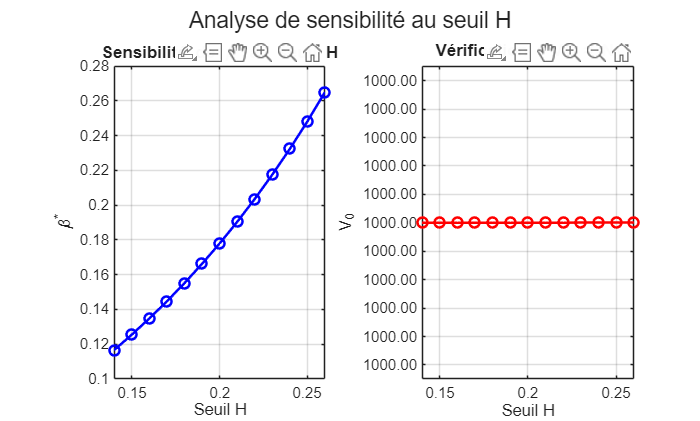


function beta_star = solve_fair_beta(RV_Q, c0, sigma0, H, M, disc_factor, N0, r, T)
    Delta = 1 / M;

    indicat = (RV_Q >= H);
    Nk      = cumsum(indicat, 1);

    k_vec   = (1:M)';
    alpha   = Nk ./ k_vec;

    RV_eff = max(RV_Q, sigma0);

    terme_fixe = exp(-r*T) * N0 + N0 * Delta * sum(disc_factor .* c0);
    terme_var  = N0 * Delta * sum(disc_factor .* mean(alpha .* RV_eff, 2));

    beta_star = (N0 - terme_fixe) / terme_var;
end

On simule sous $Q$

[S_Q, V_Q, RV_Q] = simulate_heston_Q(S0, v0, kappa, theta, xi, rho, r, q, dt, n, N, temps_obs);

## Choix des deux configurations

La première configuration est dite conservatrice : elle privilégie un coupon plancher plus élevé et un seuil de stress plus exigeant. Elle s’adresse à un investisseur recherchant davantage de stabilité, au prix d’une composante variable moins active.

La seconde configuration est dite dynamique : elle repose sur un coupon plancher plus faible, un niveau minimal de volatilité un peu plus élevé dans la formule, et un seuil H plus bas. Le mécanisme lié à la volatilité s’active donc plus souvent, ce qui conduit à une participation $\beta^\star$ d’une nature différente une fois l’équité imposée.

Les paramètres${\;c}_0$, $\sigma_0$ et $H$sont choisis de manière à refléter des ordres de grandeur réalistes de la volatilité réalisée pour un ETF large et diversifié comme ZCN, tout en permettant de différencier deux profils d’investissement.

###     **I. ****Profile conservateur:** 

On retient $\(c_0 = 1.5\%\)$, $\(\sigma_0 = 10\%\)$ et $\(H = 20\%\)$. Le niveau $\sigma_0$ correspond à une volatilité modérée, typique des phases de marché calmes à normales, tandis que le seuil $H$est fixé à un niveau élevé, de sorte que les épisodes où $\(RV_k \geq H\)$ restent relativement peu fréquents. Par conséquent, le facteur de participation $ \(\alpha_k\)$ croît lentement, ce qui limite l’impact de la composante variable du coupon. Cette configuration privilégie ainsi la stabilité des paiements et une exposition modérée à la volatilité.

c0_1     = 0.015;
sigma0_1 = 0.10;
H_1      = 0.20;

beta_1 = solve_fair_beta(RV_Q, c0_1, sigma0_1, H_1, M, disc_factor, N0, r, T)

V0_1   = price_product_Q(RV_Q, c0_1, beta_1, sigma0_1, H_1, M, disc_factor, N0, r, T)

###      **II. ****Profil dynamique:** 

On retient $\(c_0 = 1
\%\)$, $\(\sigma_0 = 12\%\)$ et $\(H = 15\%\)$. Le niveau $\sigma_0$, plus élevé, se rapproche de la volatilité moyenne observée sur l’actif, tandis que le seuil $\(H\)$ est choisi plus bas, ce qui rend les événements $\(RV_k \geq H\)$ plus fréquents. Il en résulte une augmentation plus rapide du facteur $\(\alpha_k\)$, et donc une sensibilité accrue du coupon aux variations de la volatilité réalisée. Cette configuration conduit à des coupons potentiellement plus élevés en période agitée, au prix d’une variabilité accrue.

c0_2     = 0.010;
sigma0_2 = 0.12;
H_2      = 0.15;

beta_2 = solve_fair_beta(RV_Q, c0_2, sigma0_2, H_2, M, disc_factor, N0, r, T)
V0_2   = price_product_Q(RV_Q, c0_2, beta_2, sigma0_2, H_2, M, disc_factor, N0, r, T)

Afin de comparer les deux configurations au-delà de la seule condition d’équité, on analyse la distribution des coupons simulés sous la mesure risque neutre $Q$. 

Plus précisément, on calcule des statistiques descriptives incluant la moyenne ainsi que certains quantiles empiriques des coupons annualisés. Cette analyse permet de mettre en évidence les dispersion des coupons.

## Vérification de distribution des coupons

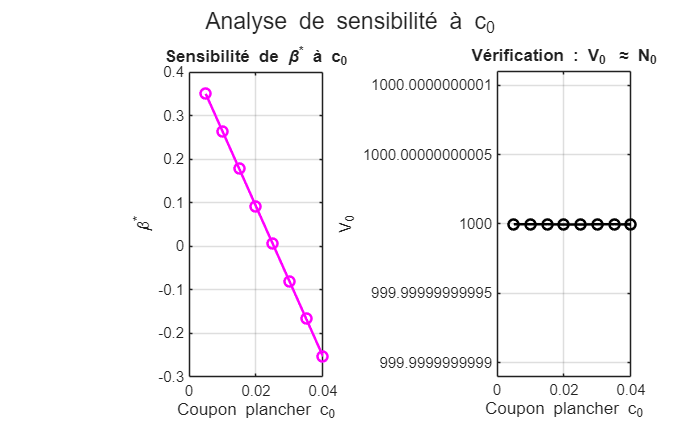

[C1_Q, alpha1_Q, RVeff1_Q] = compute_coupons(RV_Q, c0_1, beta_1, sigma0_1, H_1, M);

[C2_Q, alpha2_Q, RVeff2_Q] = compute_coupons(RV_Q, c0_2, beta_2, sigma0_2, H_2, M);
disp(quantile(C1_Q(:), [0.1 0.5 0.9]))
disp(mean(C1_Q(:)))
quantile(C2_Q(:), [0.1 0.5 0.9])
disp(mean(C2_Q(:)))

Les deux configurations présentent des valeurs de $\(\mathbb{E}^{\mathbb{Q}}[C_k]\)$ similaires, conformément à la condition d’équité $\(V_0 = N_0\)$. 

En revanche, la dispersion des coupons est plus marquée dans la seconde configuration. Cela s’explique par le fait que la configuration 1 est dominée par la composante fixe $\(c_0\)$ et un seuil $H$ plus élevé, conduisant à des paiements plus stables, tandis que la configuration 2 repose davantage sur la composante $\(\alpha_k \max(\sigma_0, RV_k)\)$ , ce qui amplifie la variabilité des coupons.

## Analyse de sensibilité

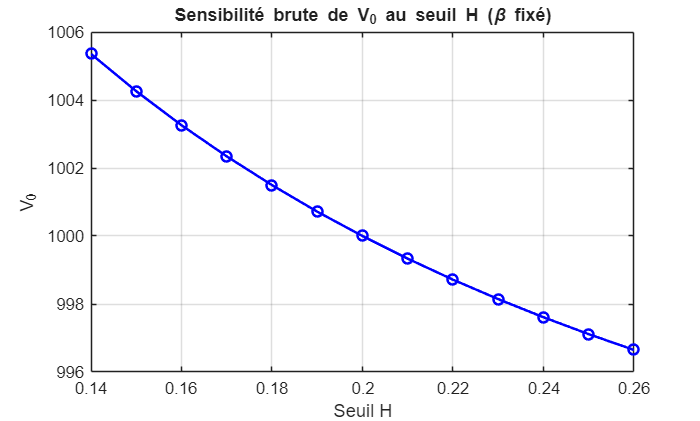

%% Sensibilité 1 : impact du seuil H sur beta* (Config 1)

H_range = 0.14 : 0.01 : 0.26;
beta_H  = zeros(size(H_range));
V0_H    = zeros(size(H_range));

for i = 1:length(H_range)
    H_i = H_range(i);

    beta_i = solve_fair_beta(RV_Q, c0_1, sigma0_1, H_i, M, disc_factor, N0, r, T);
    beta_H(i) = beta_i;

    if isnan(beta_i)

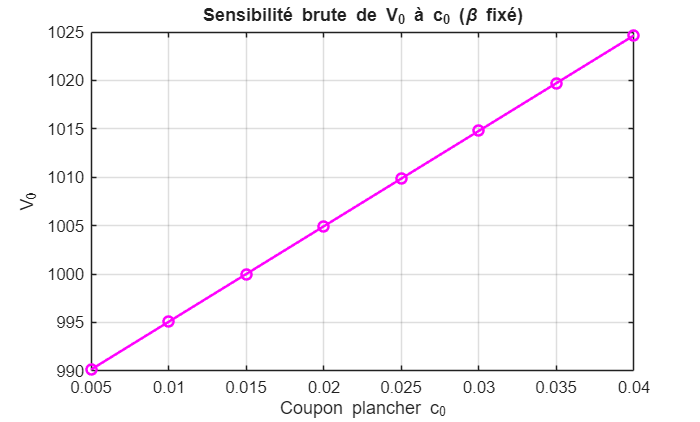

        V0_H(i) = NaN;
    else
        V0_H(i) = price_product_Q(RV_Q, c0_1, beta_i, sigma0_1, H_i, M, disc_factor, N0, r, T);
    end
end

figure;
subplot(1,2,1);
plot(H_range, beta_H, 'b-o', 'LineWidth', 1.5);
xlabel('Seuil H');
ylabel('\beta^*');
title('Sensibilité de \beta^* au seuil H');
grid on;

subplot(1,2,2);
plot(H_range, V0_H, 'r-o', 'LineWidth', 1.5);
xlabel('Seuil H');
ylabel('V_0');

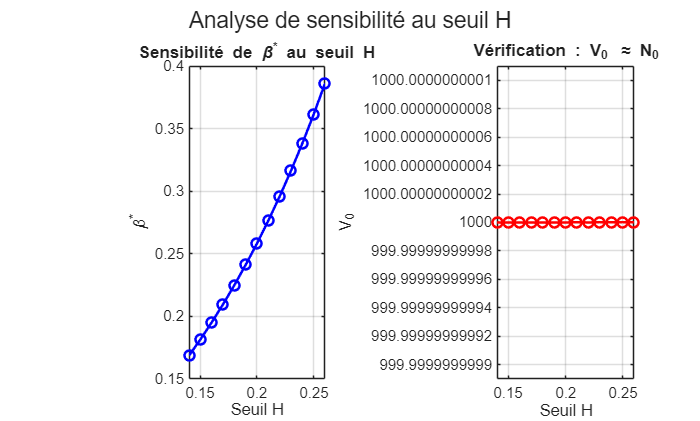

title('Vérification : V_0 \approx N_0');
grid on;
ytickformat('%.2f')   
sgtitle('Analyse de sensibilité au seuil H');

%% Sensibilité 2 : impact du coupon plancher c0 sur beta* (Config 1)

c0_range = 0.005 : 0.005 : 0.040;
beta_c0  = zeros(size(c0_range));
V0_c0    = zeros(size(c0_range));

for i = 1:length(c0_range)
    c0_i = c0_range(i);

    beta_i     = solve_fair_beta(RV_Q, c0_i, sigma0_1, H_1, M, disc_factor, N0, r, T);
    beta_c0(i) = beta_i;

    if isnan(beta_i)
        V0_c0(i) = NaN;
    else
        V0_c0(i) = price_product_Q(RV_Q, c0_i, beta_i, sigma0_1, H_1, M, disc_factor, N0, r, T);
    end
end

figure;
subplot(1,2,1);
plot(c0_range, beta_c0, 'm-o', 'LineWidth', 1.5);
xlabel('Coupon plancher c_0');
ylabel('\beta^*');
title('Sensibilité de \beta^* à c_0');
grid on;

subplot(1,2,2);
plot(c0_range, V0_c0, 'k-o', 'LineWidth', 1.5);
xlabel('Coupon plancher c_0');

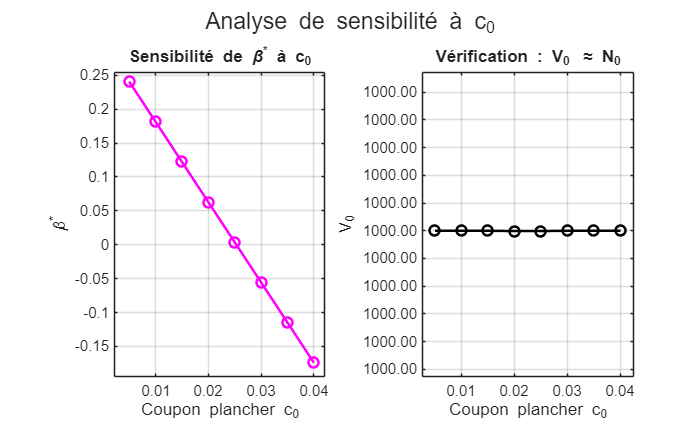

ylabel('V_0');
title('Vérification : V_0 \approx N_0');
grid on;

sgtitle('Analyse de sensibilité à c_0');
%% Sensibilité brute 1 : impact du seuil H sur V0
%% beta fixé à la valeur équitable de la configuration 1

H_range_brut = 0.14 : 0.01 : 0.26;
V0_H_brut    = zeros(size(H_range_brut));

for i = 1:length(H_range_brut)
    H_i = H_range_brut(i);

    V0_H_brut(i) = price_product_Q(RV_Q, c0_1, beta_1, sigma0_1, H_i, M, disc_factor, N0, r, T);
end

figure;
plot(H_range_brut, V0_H_brut, 'b-o', 'LineWidth', 1.5);
xlabel('Seuil H');
ylabel('V_0');
title('Sensibilité brute de V_0 au seuil H (\beta fixé)');
grid on;
%% Sensibilité brute 2 : impact du coupon plancher c0 sur V0
%% beta fixé à la valeur équitable de la configuration 1

c0_range_brut = 0.005 : 0.005 : 0.040;
V0_c0_brut    = zeros(size(c0_range_brut));

for i = 1:length(c0_range_brut)
    c0_i = c0_range_brut(i);

    V0_c0_brut(i) = price_product_Q(RV_Q, c0_i, beta_1, sigma0_1, H_1, M, disc_factor, N0, r, T);
end

figure;
plot(c0_range_brut, V0_c0_brut, 'm-o', 'LineWidth', 1.5);

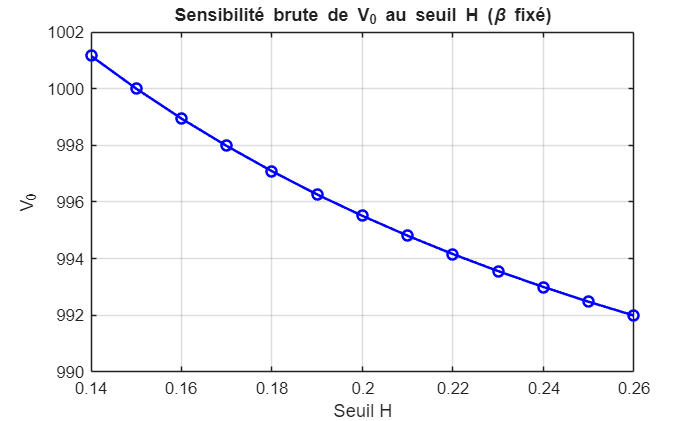

xlabel('Coupon plancher c_0');
ylabel('V_0');
title('Sensibilité brute de V_0 à c_0 (\beta fixé)');
grid on;
%% Sensibilité 1 : impact du seuil H sur beta* (Config 2)

H_range = 0.14 : 0.01 : 0.26;
beta_H  = zeros(size(H_range));
V0_H    = zeros(size(H_range));

for i = 1:length(H_range)
    H_i = H_range(i);

    beta_i = solve_fair_beta(RV_Q, c0_2, sigma0_2, H_i, M, disc_factor, N0, r, T);
    beta_H(i) = beta_i;

    if isnan(beta_i)
        V0_H(i) = NaN;
    else
        V0_H(i) = price_product_Q(RV_Q, c0_2, beta_i, sigma0_2, H_i, M, disc_factor, N0, r, T);

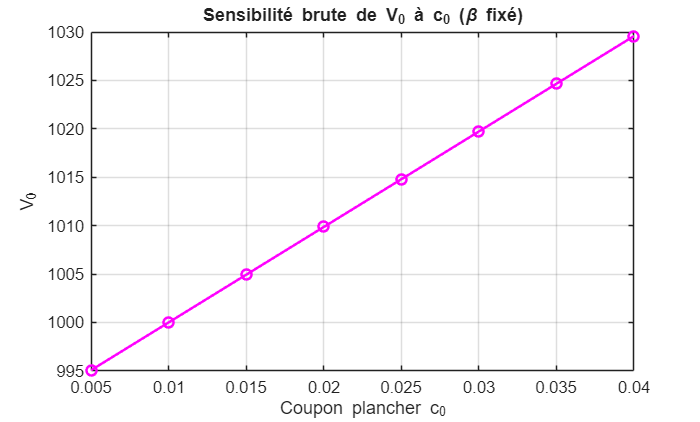

    end
end

figure;
subplot(1,2,1);
plot(H_range, beta_H, 'b-o', 'LineWidth', 1.5);
xlabel('Seuil H');
ylabel('\beta^*');
title('Sensibilité de \beta^* au seuil H');
grid on;

subplot(1,2,2);
plot(H_range, V0_H, 'r-o', 'LineWidth', 1.5);
xlabel('Seuil H');
ylabel('V_0');
title('Vérification : V_0 \approx N_0');
grid on;


sgtitle('Analyse de sensibilité au seuil H');
%% Sensibilité 2 : impact du coupon plancher c0 sur beta* (Config 2)


c0_range = 0.005 : 0.005 : 0.040;
beta_c0  = zeros(size(c0_range));
V0_c0    = zeros(size(c0_range));

for i = 1:length(c0_range)
    c0_i = c0_range(i);

    beta_i     = solve_fair_beta(RV_Q, c0_i, sigma0_2, H_2, M, disc_factor, N0, r, T);
    beta_c0(i) = beta_i;

    if isnan(beta_i)
        V0_c0(i) = NaN;
    else
        V0_c0(i) = price_product_Q(RV_Q, c0_i, beta_i, sigma0_2, H_2, M, disc_factor, N0, r, T);
    end
end

figure;
subplot(1,2,1);
plot(c0_range, beta_c0, 'm-o', 'LineWidth', 1.5);
xlabel('Coupon plancher c_0');
ylabel('\beta^*');
title('Sensibilité de \beta^* à c_0');
grid on;

subplot(1,2,2);
plot(c0_range, V0_c0, 'k-o', 'LineWidth', 1.5);
xlabel('Coupon plancher c_0');
ylabel('V_0');

  Moyenne rendement - COnfig 1: 1.5667%


title('Vérification : V_0 \approx N_0');

  Ecart-type rendement : 0.1517%


grid on;

  Minimum : 1.5000%


ytickformat('%.2f')   

  Maximum : 3.5900%


  Quantiles [5%, 10%, 50%, 90%, 95%] :


sgtitle('Analyse de sensibilité à c_0');

    1.5000    1.5000    1.5000    1.7580    1.8956



  Moyenne rendement - Config 2 : 1.5384%


  Ecart-type rendement : 0.4229%


%% Sensibilité brute 1 : impact du seuil H sur V0

  Minimum : 1.0000%


%% beta fixé à la valeur équitable de la configuration 2

  Maximum : 4.1942%


  Quantiles [5%, 10%, 50%, 90%, 95%] :


H_range_brut = 0.14 : 0.01 : 0.26;

    1.0000    1.0579    1.4561    2.1251    2.3526



V0_H_brut    = zeros(size(H_range_brut));

for i = 1:length(H_range_brut)
    H_i = H_range_brut(i);


VaR_95_1 = 1.5000

    V0_H_brut(i) = price_product_Q(RV_Q, c0_2, beta_2, sigma0_2, H_i, M, disc_factor, N0, r, T);

ES_95_1 = 1.5000

end


VaR_95_2 = 1

figure;

ES_95_2 = 1

plot(H_range_brut, V0_H_brut, 'b-o', 'LineWidth', 1.5);
xlabel('Seuil H');
ylabel('V_0');
title('Sensibilité brute de V_0 au seuil H (\beta fixé)');
grid on;
%% Sensibilité brute 2 : impact du coupon plancher c0 sur V0
%% beta fixé à la valeur équitable de la configuration 1

c0_range_brut = 0.005 : 0.005 : 0.040;
V0_c0_brut    = zeros(size(c0_range_brut));

for i = 1:length(c0_range_brut)
    c0_i = c0_range_brut(i);

    V0_c0_brut(i) = price_product_Q(RV_Q, c0_i, beta_2, sigma0_2, H_2, M, disc_factor, N0, r, T);
end

figure;
plot(c0_range_brut, V0_c0_brut, 'm-o', 'LineWidth', 1.5);
xlabel('Coupon plancher c_0');
ylabel('V_0');
title('Sensibilité brute de V_0 à c_0 (\beta fixé)');
grid on;

## Analyse sous P du produit volatilite 1

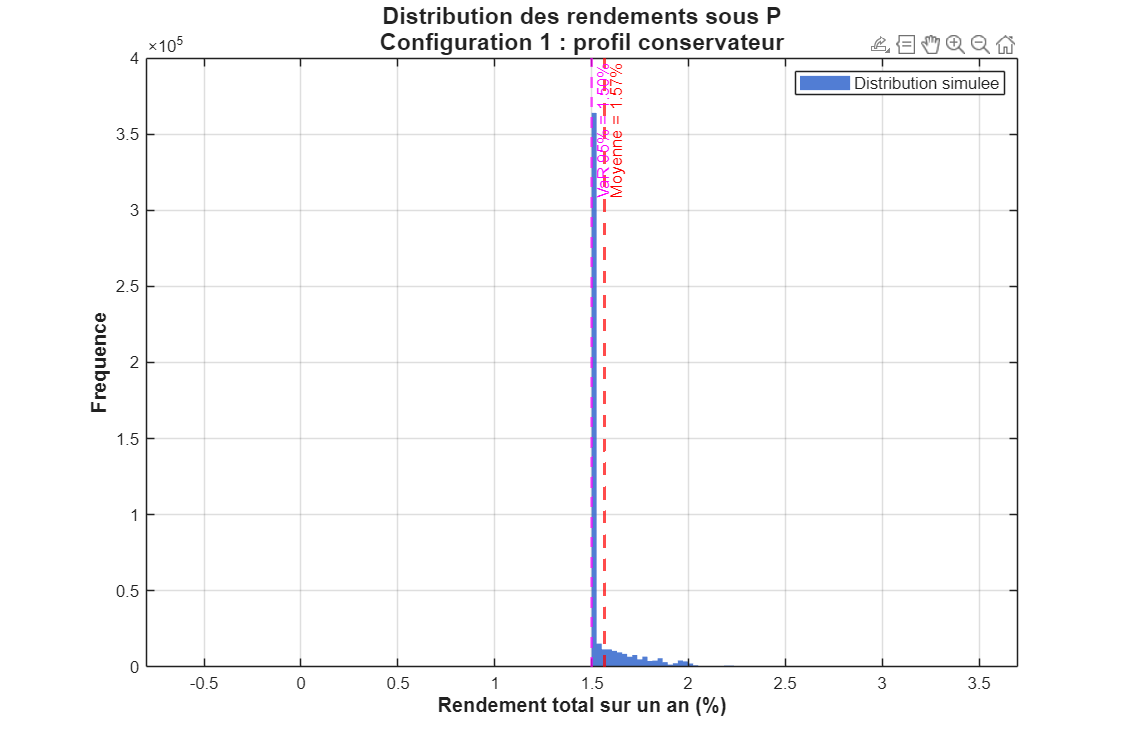

mu_P = 0.1108;

rng(12345, 'twister');

theta_P = 0.017771;
kappa_P = 27.900162;
xi_P = 0.550470;
rho_P = -0.746108;

[S_P, V_P, RV_P] = simulate_heston_P(S0, v0, kappa_P, theta_P, xi_P, rho_P, mu_P, dt, n, N, temps_obs);

%% Coupons sous P avec les beta calibres sous Q

[C1_P, alpha1_P, RVeff1_P] = compute_coupons(RV_P, c0_1, beta_1, sigma0_1, H_1, M);
[C2_P, alpha2_P, RVeff2_P] = compute_coupons(RV_P, c0_2, beta_2, sigma0_2, H_2, M);

Delta = 1 / M;

coupon_total_1_P = N0 * Delta * sum(C1_P, 1);
coupon_total_2_P = N0 * Delta * sum(C2_P, 1);

CF_total_1_P = N0 + coupon_total_1_P;
CF_total_2_P = N0 + coupon_total_2_P;

%% Rendement total sur un an par rapport au nominal

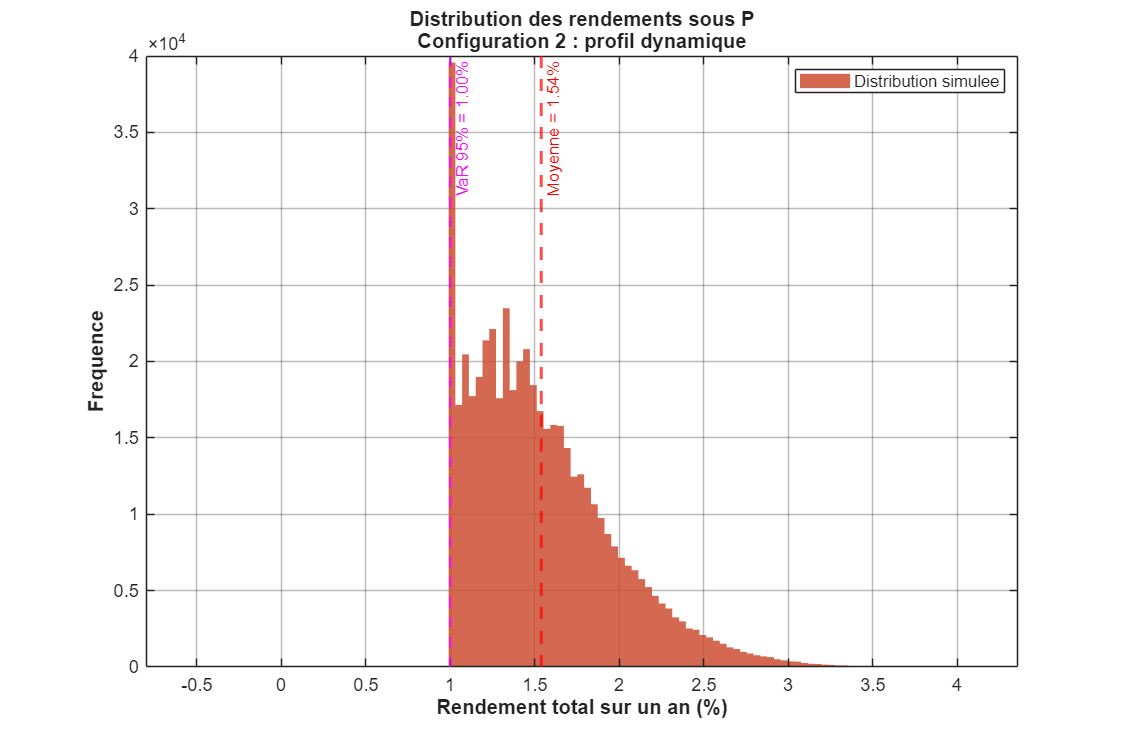


rendement_1_P = (CF_total_1_P - N0) / N0 * 100;
rendement_2_P = (CF_total_2_P - N0) / N0 * 100;

%% Statistiques descriptives sous P
fprintf('  Moyenne rendement - COnfig 1: %.4f%%\n', mean(rendement_1_P));
fprintf('  Ecart-type rendement : %.4f%%\n', std(rendement_1_P));
fprintf('  Minimum : %.4f%%\n', min(rendement_1_P));
fprintf('  Maximum : %.4f%%\n', max(rendement_1_P));
disp('  Quantiles [5%, 10%, 50%, 90%, 95%] :');
disp(quantile(rendement_1_P, [0.05 0.10 0.50 0.90 0.95]));
fprintf('  Moyenne rendement - Config 2 : %.4f%%\n', mean(rendement_2_P));
fprintf('  Ecart-type rendement : %.4f%%\n', std(rendement_2_P));
fprintf('  Minimum : %.4f%%\n', min(rendement_2_P));
fprintf('  Maximum : %.4f%%\n', max(rendement_2_P));
disp('  Quantiles [5%, 10%, 50%, 90%, 95%] :');
disp(quantile(rendement_2_P, [0.05 0.10 0.50 0.90 0.95]));
%% VaR et ES empiriques sous P

alpha = 0.05;

VaR_95_1 = prctile(rendement_1_P, alpha * 100)
ES_95_1  = mean(rendement_1_P(rendement_1_P <= VaR_95_1))

VaR_95_2 = prctile(rendement_2_P, alpha * 100)
ES_95_2  = mean(rendement_2_P(rendement_2_P <= VaR_95_2))
% Histogramme configuration 1

figure('Name', 'Configuration conservatrice sous P', ...
       'Position', [100, 100, 900, 600]);

mu_1     = mean(rendement_1_P);
VaR_95_1 = prctile(rendement_1_P, 5);

h1 = histogram(rendement_1_P, 80, ...
    'FaceColor', [0.2 0.4 0.8], ...
    'EdgeColor', 'none', ...
    'FaceAlpha', 0.85);
hold on;

binEdges_1   = h1.BinEdges;
binCounts_1  = h1.Values;
binCenters_1 = (binEdges_1(1:end-1) + binEdges_1(2:end)) / 2;
maskVaR_1    = binCenters_1 <= VaR_95_1;

bar(binCenters_1(maskVaR_1), binCounts_1(maskVaR_1), ...
    1.0, ...
    'FaceColor', [0.85 0.3 0.3], ...
    'FaceAlpha', 0.35, ...
    'EdgeColor', 'none');

xline(mu_1, '--r', ...
    ['Moyenne = ' num2str(mu_1, '%.2f') '%'], ...
    'LineWidth', 1.8);


xline(VaR_95_1, '--m', ...
    ['VaR 95% = ' num2str(VaR_95_1, '%.2f') '%'], ...
    'LineWidth', 1.5);

xlabel('Rendement total sur un an (%)', ...
    'FontSize', 12, 'FontWeight', 'bold');
ylabel('Frequence', ...
    'FontSize', 12, 'FontWeight', 'bold');

title({'Distribution des rendements sous P', ...
       'Configuration 1 : profil conservateur'}, ...
      'FontSize', 14, ...
      'FontWeight', 'bold', ...
      'Interpreter', 'none');

legend(h1, 'Distribution simulee', ...
    'Location', 'northeast', ...
    'FontSize', 10);

grid on;
box on;
% Histogramme configuration 2

figure('Name', 'Configuration dynamique sous P', ...
       'Position', [150, 150, 900, 600]);

mu_2     = mean(rendement_2_P);
VaR_95_2 = prctile(rendement_2_P, 5);

h2 = histogram(rendement_2_P, 80, ...
    'FaceColor', [0.8 0.3 0.2], ...
    'EdgeColor', 'none', ...
    'FaceAlpha', 0.85);
hold on;

binEdges_2   = h2.BinEdges;
binCounts_2  = h2.Values;
binCenters_2 = (binEdges_2(1:end-1) + binEdges_2(2:end)) / 2;
maskVaR_2    = binCenters_2 <= VaR_95_2;

bar(binCenters_2(maskVaR_2), binCounts_2(maskVaR_2), ...
    1.0, ...
    'FaceColor', [0.85 0.3 0.3], ...
    'FaceAlpha', 0.35, ...
    'EdgeColor', 'none');

xline(mu_2, '--r', ...
    ['Moyenne = ' num2str(mu_2, '%.2f') '%'], ...
    'LineWidth', 1.8);

xline(VaR_95_2, '--m', ...
    ['VaR 95% = ' num2str(VaR_95_2, '%.2f') '%'], ...
    'LineWidth', 1.5);

xlabel('Rendement total sur un an (%)', ...
    'FontSize', 12, 'FontWeight', 'bold');
ylabel('Frequence', ...
    'FontSize', 12, 'FontWeight', 'bold');

title({'Distribution des rendements sous P', ...
       'Configuration 2 : profil dynamique'}, ...
      'FontSize', 14, ...
      'FontWeight', 'bold', ...
      'Interpreter', 'none');

legend(h2, 'Distribution simulee', ...
    'Location', 'northeast', ...
    'FontSize', 10);

grid on;
box on;

ax = gca;
ax.FontSize = 11;
ax.GridAlpha = 0.3;


function [S, V, RV] = simulate_heston_P(S0, v0, kappa, theta, xi, rho, mu_P, dt, n, N, temps_obs)

    M = length(temps_obs);

    S = zeros(n+1, N);
    V = zeros(n+1, N);

    S(1,:) = S0;
    V(1,:) = v0;

    L = [1, 0; rho, sqrt(1-rho^2)];

    for t = 1:n
        Z      = randn(2, N);
        Z_corr = L * Z;

        dWs = sqrt(dt) * Z_corr(1,:);
        dWv = sqrt(dt) * Z_corr(2,:);

        Vt = max(V(t,:), 0);

        V(t+1,:) = max(V(t,:) + kappa*(theta - Vt)*dt + xi*sqrt(Vt).*dWv, 0);

        S(t+1,:) = S(t,:) .* exp((mu_P - 0.5*Vt)*dt + sqrt(Vt).*dWs);
    end

    Rets = log(S(2:end,:) ./ S(1:end-1,:));

    RV = zeros(M, N);
    idx_prev = 0;

    for k = 1:M
        idx_k = temps_obs(k);

        rets_k = Rets(idx_prev+1:idx_k, :);
        nk     = size(rets_k, 1);

        RV(k,:) = sqrt(252 / nk * sum(rets_k.^2, 1));

        idx_prev = idx_k;
    end
end